# Filtro de Bayes

Aplicação recursiva do T**eorema de Bayes** para eliminação de ruído é o chamado** Filtro de Bayes (Técnica de Inferência Estatística)**.

Teorema de Bayes permite que seja possível calcular probabilidades condicionais.


$$P(A|B)=\frac{P(B|A) P(A)}{P(B)}$$


Para usar o **Filtro de Bayes** é necessário usar o **Teorema do Limite Central**, que diz que qualquer aleatória é possível obter uma variável normal (gaussiana).

As incertezas das medidas vão ser modeladas pelas **Funções Densidade de Probabilidade (FDP)**.

A resposta do robô vai ser uma funão gaussiana.

Na robótica móvel o interesse é na posição do robô. Para se obter essa posição tem-se que usar **sensores**. Tomando **X** como a posição do robô e **Z** a leitura de sensores, então usando Bayes tem-se que: 

**X**: posição do robô

**Z**: leitura dos sensores


$$P(X|Z)=\frac{P(Z|X) P(X)}{P(Z)}$$


Uma observação é que a leitura dos sensores falham. Logo, todo sensor é modelado por uma variável estatística, **FDP**.

Logo, o número que o sensor informa deve ser transformado em uma gaussiana.

A função densidade de probabilidade da gaussiana é dada por:


$$f(x) = \frac{1}{\sqrt{2\pi\sigma^2}}e^{-\frac{1}{2}\left( \frac{x-\mu}{\sigma} \right)^2}$$


Para montar uma gaussiana é necessários dos fatores, a média $\mu \;$e o desvio padrão $\sigma \;$.

A média ($\mu \;$) vai ser a medida do sensor, o desvio vai ser obtido pela consulta do fabricante. Caso esse desvio não seja informado, então é necessário encontrar por experimentação. Pode-se usar por exemplo uma calibração aplicando **Teorema do Limite Central** encontrando as médias.

Um detalhe é que o robô não vai se mover enquanto ele não descobrir onde ele está.

**Probabilidade a Priori P(X)** inicial. A primeira distribuição do robô é uniforme. Todas as posições disponíveis têm a mesma chance de ser a verdadeira.

**Probabilidade à Posteriori P(Z|X)** obtida do sensor. A primeira medida é transformada em uma gaussiana.

Aplicando o Teorema de Bayes, tem-se a multiplicação das duas funções.


$$P(X|Z)=\frac{P(Z|X) P(X)}{P(Z)}$$


Lembrando que $P\left(Z\right)$deve ser normalizado.


$$P(Z) = \int_{-\infty}^{\infty} P(Z|X)P(X)dX$$


Uma vez obtida informações sobre as funções, é realizar cálculos estatísticos dos momentos.

A primeira é a esperança de $P\left(X\left|Z\right.\right)$, que é dado por:


$$\mu=E(X)=\int_{-\infty}^{\infty}xf(x)dx$$


onde $f\left(x\right)=P\left(X\left|Z\right.\right)$

O primeiro valor da esperança será o valor da medida dado pelo sensor, no entanto, nos próximos passos o valor mudará.

A segunda medida é o desvio padrão da FDP de Bayes.


$$\sigma=\sqrt{E(X^2)}=\sqrt{\int_{-\infty}^{\infty}(x-\mu)^2 f(x)dx}$$


onde $f\left(x\right)=P\left(Z\left|X\right.\right)$

O primeiro desvio padrão será o do próprio sensor.

O desvio padrão é o ponto de inflexão da gaussiana, e oferece 68,25% de confiança.

**Intervalo de Confiança** é uma percentagem que sugere um grau de confiança de que a medida verdadeira (desejada) está dentro de um certo intervalo calculado.

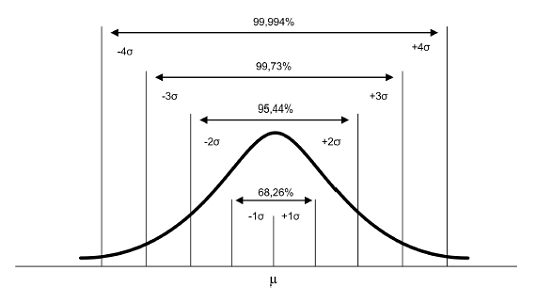

A resposta final é uma gaussiana com um intervalo de confiança.

É executada várias rodadas.


$$P(X)_t = P(X|Z)_{t-1}$$


O que Bayes faz é eliminar com o passar das iterações o erro do sensor.

O **Filtro de Bayes** torna a incerteza cada vez menor.

O **Filtro de Bayes** é recursivo. A satisfação do número de iterações necessárias é atingit o padrão desejado em P(X|Z), desvio padrão ou raiz dele.

clear all


bayes_filter = BayesFilter(0, 10, 5, 1)

bayes_filter =   BayesFilter with properties:

        x_ll: 0
        x_rl: 10
          x0: 5
    sigma_z0: 1
        seed: 100
      spaces: 1000


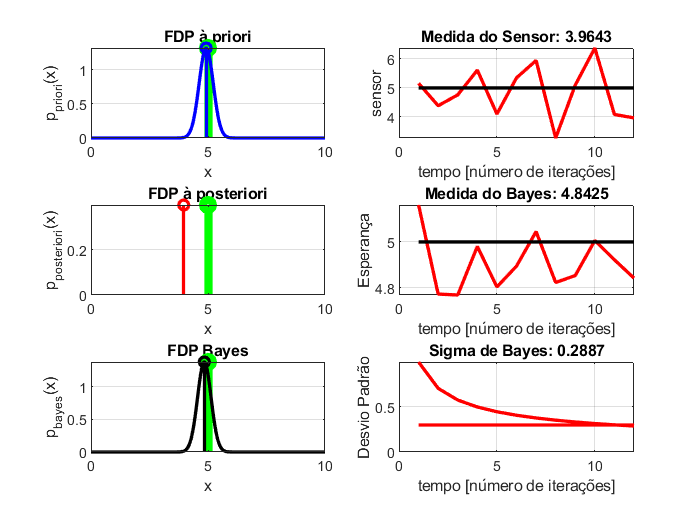


bayes_filter.runSimulation()